cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'MX201 Vibration Data for analysis.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

% === Inject Linear Ramps Before Faults in X/Y/Z RMS and Trend Columns ===

rampLength = 600;

% ------ X Axis -------
wasModifiedX = false(height(data), 1);

for idx = rampLength+1:height(data)
    if data.X_RMS(idx) > 8.5 && ~any(wasModifiedX(idx - rampLength : idx - 1))
        baseVal = data.X_RMS(idx - rampLength);
        peakVal = data.X_RMS(idx);
        data.X_RMS(idx - rampLength + 1 : idx - 1) = linspace(baseVal, peakVal, rampLength - 1)';

        baseT = data.XRMS_Trend(idx - rampLength);
        peakT = data.XRMS_Trend(idx);
        data.XRMS_Trend(idx - rampLength + 1 : idx - 1) = linspace(baseT, peakT, rampLength - 1)';

        wasModifiedX(idx - rampLength + 1 : idx - 1) = true;
    end
end

% ------ Y Axis -------
wasModifiedY = false(height(data), 1);

for idx = rampLength+1:height(data)
    if data.Y_RMS(idx) > 8.5 && ~any(wasModifiedY(idx - rampLength : idx - 1))
        baseVal = data.Y_RMS(idx - rampLength);
        peakVal = data.Y_RMS(idx);
        data.Y_RMS(idx - rampLength + 1 : idx - 1) = linspace(baseVal, peakVal, rampLength - 1)';

        baseT = data.YRMS_Trend(idx - rampLength);
        peakT = data.YRMS_Trend(idx);
        data.YRMS_Trend(idx - rampLength + 1 : idx - 1) = linspace(baseT, peakT, rampLength - 1)';

        wasModifiedY(idx - rampLength + 1 : idx - 1) = true;
    end
end

% ------ Z Axis -------
wasModifiedZ = false(height(data), 1);

for idx = rampLength+1:height(data)
    if data.Z_RMS(idx) > 8.5 && ~any(wasModifiedZ(idx - rampLength : idx - 1))
        baseVal = data.Z_RMS(idx - rampLength);
        peakVal = data.Z_RMS(idx);
        data.Z_RMS(idx - rampLength + 1 : idx - 1) = linspace(baseVal, peakVal, rampLength - 1)';

        baseT = data.ZRMS_Trend(idx - rampLength);
        peakT = data.ZRMS_Trend(idx);
        data.ZRMS_Trend(idx - rampLength + 1 : idx - 1) = linspace(baseT, peakT, rampLength - 1)';

        wasModifiedZ(idx - rampLength + 1 : idx - 1) = true;
    end
end

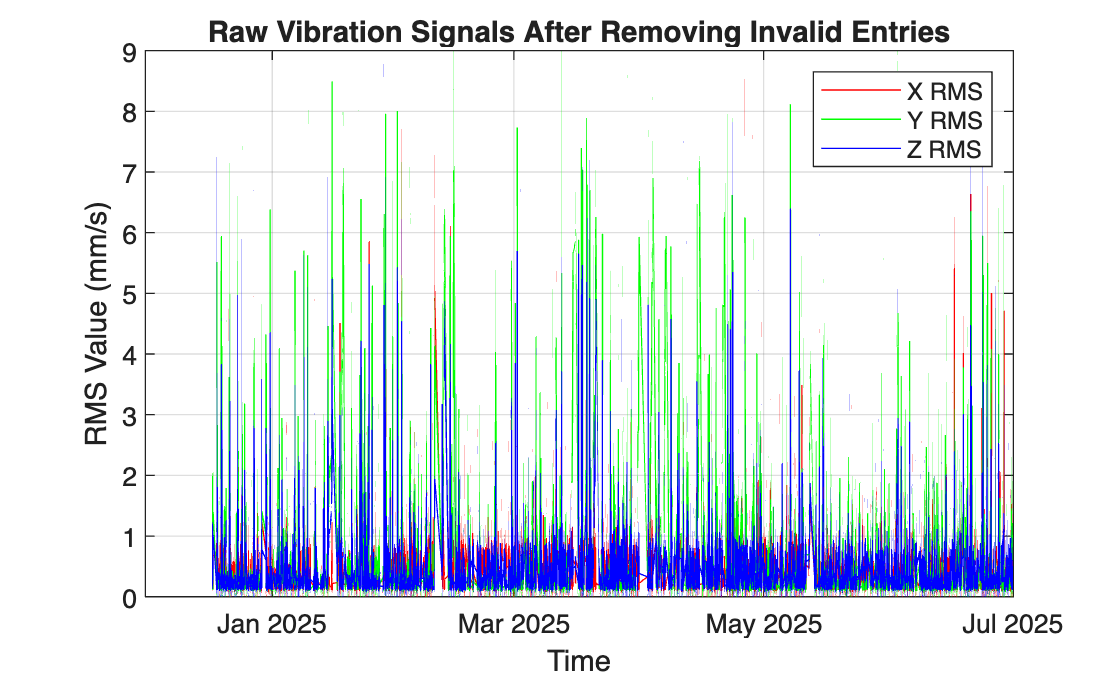

% Visualize raw vibration signals (cleaned)
figure;
plot(data.DateTime, data.X_RMS, 'r');
hold on;
plot(data.DateTime, data.Y_RMS, 'g');
plot(data.DateTime, data.Z_RMS, 'b');
xlabel('Time');
ylabel('RMS Value (mm/s)');
title('Raw Vibration Signals After Removing Invalid Entries');
legend('X RMS', 'Y RMS', 'Z RMS');
grid on;


% Step 1: Identify high-RMS indices
highRMS = data.X_RMS > 8.5 | data.Y_RMS > 8.5 | data.Z_RMS > 8.5;
highRMSIdx = find(highRMS);

fprintf("📌 High-RMS entries (X, Y, or Z > 8.5 mm/s):\n");

📌 High-RMS entries (X, Y, or Z > 8.5 mm/s):


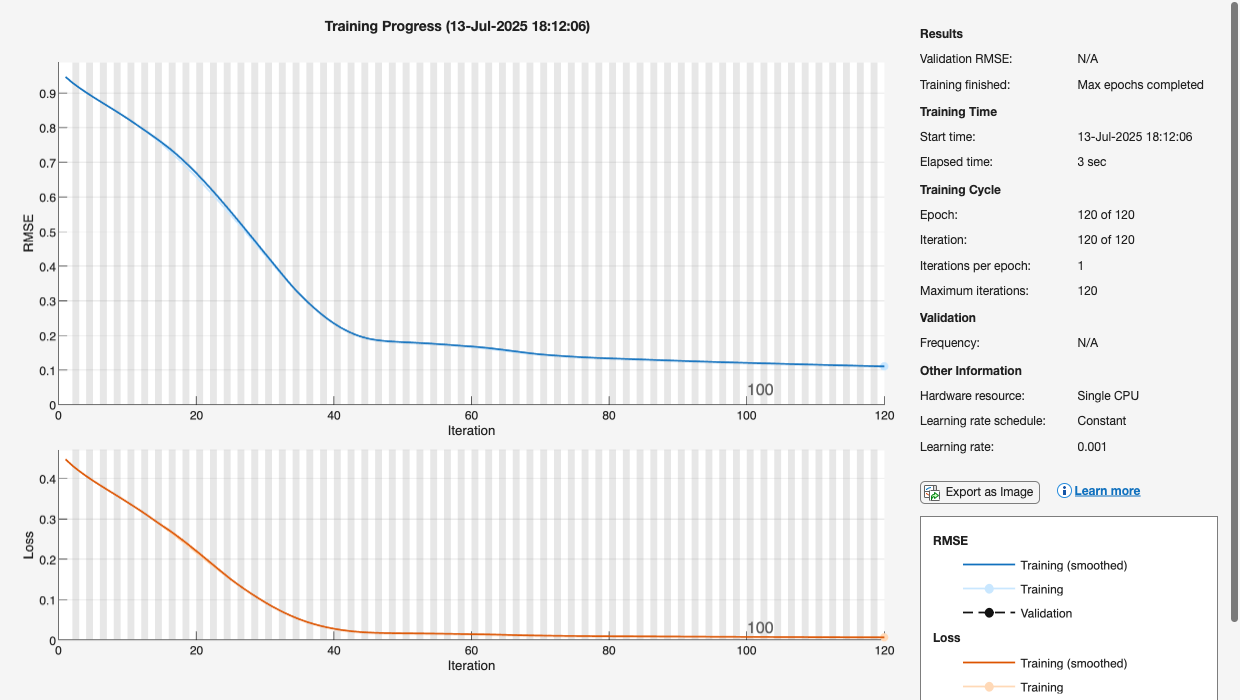

for i = 1:length(highRMSIdx)
    idx = highRMSIdx(i);
    fprintf("Index %5d | Time: %s | X: %.2f | Y: %.2f | Z: %.2f\n", ...
        idx, string(data.DateTime(idx)), ...
        data.X_RMS(idx), data.Y_RMS(idx), data.Z_RMS(idx));
end

% Step 2: Mark ±50-sample windows for removal
removeMask = false(height(data), 1);
window = 50;

for idx = highRMSIdx'
    fromIdx = max(1, idx - window);
    toIdx = min(height(data), idx + window);
    removeMask(fromIdx:toIdx) = true;
end

% Step 3: Remove those entries from data
data = data(~removeMask, :);

% Step 4: Now safely construct the features table
features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];

% Remove missing values from both features and data ⬅️ NEW LINE
missingMask = any(ismissing(features), 2);
features = features(~missingMask, :);
data = data(~missingMask, :);  % align data table with features

% ---- Normalize using training-only range ----
X_full = features{:,:};
numTrain = round(0.5 * size(X_full, 1));
train_min = min(X_full(1:numTrain, :));
train_max = max(X_full(1:numTrain, :));

X = (X_full - train_min) ./ (train_max - train_min);
X = max(min(X, 1), 0);  % clamp to [0,1]

% Optional detrending
% X = detrend(X);
% X = diff(X);

numTrain = round(0.5 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

% Autoencoder
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

% Train and Predict
net = trainNetwork(XTrain, XTrain, layers, options);

% 🧠 Assumes 'net' is your trained autoencoder from healthy data

% Reload full data (only removing zero-RMS entries)
filename = 'MX201 Vibration Data for analysis.xlsx';
dataFull = readtable(filename, 'VariableNamingRule', 'preserve');
dataFull.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
dataFull.DateTime = datetime(dataFull.DateTime);

validIdx = dataFull.X_RMS > 0 | dataFull.Y_RMS > 0 | dataFull.Z_RMS > 0;
dataFull = dataFull(validIdx, :);  % ⚠️ only remove invalid, keep faults

% Feature engineering
featuresFull = table;
featuresFull.XRMS = dataFull.X_RMS;
featuresFull.YRMS = dataFull.Y_RMS;
featuresFull.ZRMS = dataFull.Z_RMS;
featuresFull.XRMS_Trend = dataFull.XRMS_Trend;
featuresFull.YRMS_Trend = dataFull.YRMS_Trend;
featuresFull.ZRMS_Trend = dataFull.ZRMS_Trend;
featuresFull.MagRMS = sqrt(dataFull.X_RMS.^2 + dataFull.Y_RMS.^2 + dataFull.Z_RMS.^2);
featuresFull.dXRMS = [NaN; diff(dataFull.X_RMS)];
featuresFull.dYRMS = [NaN; diff(dataFull.Y_RMS)];
featuresFull.dZRMS = [NaN; diff(dataFull.Z_RMS)];
featuresFull = rmmissing(featuresFull);
dataFull = dataFull(end - height(featuresFull) + 1 : end, :);  % realign time

% Normalize using old training min-max
X_fullRaw = featuresFull{:,:};
X_fullNorm = (X_fullRaw - train_min) ./ (train_max - train_min);
X_fullNorm = max(min(X_fullNorm, 1), 0);

% Predict with autoencoder
X_testSeq = {X_fullNorm'};
Y_testPred = predict(net, X_testSeq);
reconLoss_full = sqrt(mean((X_testSeq{1} - Y_testPred{1}).^2, 1));
timestamps_full = dataFull.DateTime(end - numel(reconLoss_full) + 1:end);

% Plot reconstruction loss over time
figure;
plot(timestamps_full, reconLoss_full, 'b');
xlabel('Time');
ylabel('Reconstruction RMSE');
title('Autoencoder RMSE on Full Dataset (with Faults)');
grid on;

% Optional: Add threshold from clean RMSE
threshold = prctile(reconLoss_full(1:round(0.5*end)), 99.95);
yline(threshold, '--r', sprintf('99.95%% Threshold = %.4f', threshold));

legend('RMSE', '99.95% Threshold', 'Location', 'northwest');


% Assuming `reconLoss` is your RMSE vector
% and `threshold` is already defined (e.g., using prctile)

% Count how many values exceed the threshold
numAboveThreshold = sum(reconLoss > threshold);

% Print the result
fprintf('🔍 Number of RMSE values above threshold (%.4f): %d\n', threshold, numAboveThreshold);
% Get indices where RMSE > threshold
exceedingIdx = find(reconLoss > threshold);

% Optionally get the corresponding timestamps
exceedingTimes = timestamps(exceedingIdx);  % assuming `timestamps` aligns with `reconLoss`

% Display sample of them
disp("Sample timestamps where RMSE exceeded threshold:");
disp(exceedingTimes);  % print first 10 for brevity

%% --------------------------------------------
% 📈 Predicting RMSE 600 Steps Ahead from Sliding Windows (LSTM)
% --------------------------------------------

% Smooth RMSE (optional)
smoothRMSE = double(reconLoss);  % you can disable if needed

% Split
rmseTrain = smoothRMSE(1:round(0.5*length(smoothRMSE)));  % train LSTM on 50%
rmseForecastRegion = smoothRMSE(round(0.5*length(smoothRMSE))+1:end);  % forecast zone

% Define LSTM training dataset (windowed)
windowSize = 100;
X_lstm = {};
Y_lstm = {};

for i = 1:(length(rmseTrain) - windowSize)
    X_lstm{end+1} = rmseTrain(i : i + windowSize - 1);  % sequence input
    Y_lstm{end+1} = rmseTrain(i + windowSize);          % next step target
end

X_lstm = X_lstm';
Y_lstm = cell2mat(Y_lstm');  % convert to numeric vector

% Define LSTM layers
layersLSTM = [
    sequenceInputLayer(1)
    lstmLayer(50, 'OutputMode','last')
    fullyConnectedLayer(1)
    regressionLayer
];

optionsLSTM = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.005, ...
    'GradientThreshold', 1, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false);

fprintf("⏳ Training LSTM on RMSE (first 50%%)...\n");
netLSTM = trainNetwork(X_lstm, Y_lstm, layersLSTM, optionsLSTM);
fprintf("✅ LSTM training complete.\n");


%% 🔁 Rolling Window Forecasting (600 steps ahead)
forecastHorizon = 600;
stride = 30;
numForecasts = floor((length(rmseForecastRegion) - windowSize - forecastHorizon) / stride) + 1;
forecast600Results = table('Size', [numForecasts 3], ...
    'VariableTypes', {'double','datetime','cell'}, ...
    'VariableNames', {'WindowIndex','WindowStartTime','AllForecastedSteps'});

fprintf("📈 Starting %d rolling forecasts...\n", numForecasts);

for i = 1:numForecasts
    idxStart = (i-1)*stride + 1;
    idxEnd = idxStart + windowSize - 1;
    inputSeq = rmseForecastRegion(idxStart:idxEnd);
    inputSeq = inputSeq(:)';  % 1 × windowSize row vector

    forecastSteps = zeros(1, forecastHorizon);
    for j = 1:forecastHorizon
        nextVal = predict(netLSTM, {inputSeq});
        forecastSteps(j) = double(nextVal);
        inputSeq = [inputSeq(2:end), double(nextVal)];  % slide
    end

    forecast600Results.WindowIndex(i) = i;
    forecast600Results.WindowStartTime(i) = timestamps(round(0.5*length(smoothRMSE)) + idxStart);
    forecast600Results.AllForecastedSteps{i} = forecastSteps;
    fprintf("On forecast number %d\n", i);
end

fprintf("✅ Forecasting complete. Showing sample:\n");
disp(forecast600Results(1:10, :));

% Optional: Save results
% writetable(forecast600Results, '600StepAheadForecasts.csv');


% Preallocate new column
forecast600Results.NumAboveThreshold = zeros(height(forecast600Results), 1);

% Loop through the existing forecasted results
for i = 1:height(forecast600Results)
    forecastVec = forecast600Results.AllForecastedSteps{i};
    forecast600Results.NumAboveThreshold(i) = sum(forecastVec > threshold);
end

% Compute max forecasted value per row
maxForecastedValue = cellfun(@max, forecast600Results.AllForecastedSteps);

% Append as new column
forecast600Results.MaxForecastedValue = maxForecastedValue;

% Move it to 4th position
forecast600Results = movevars(forecast600Results, 'MaxForecastedValue', 'After', 'WindowStartTime');


% Rearrange columns
forecast600Results = forecast600Results(:, [1 2 end 3:(width(forecast600Results)-1)]);
sortedResults = sortrows(forecast600Results, 'MaxForecastedValue', 'descend');
disp(sortedResults(1:10, :));  % Display top 10 rows

disp(forecast600Results(1:10, :));